clc,clear,close all
x = [1,2,3,4,5];        % 已知点x坐标
y = [4,4.5,6,8,8.5];    % 已知点y坐标
omega = [2 1 3 1 1];    % 权重
xx = linspace(x(1),x(end),100);
syms t
varphi = [1,t,t^2];
[yy,S,a] = least_squares(x,y,omega,varphi,xx);

yy =     3.8843    3.9227    3.9614    4.0003    4.0395    4.0788    4.1184    4.1582    4.1983    4.2386    4.2791    4.3198    4.3607    4.4019    4.4433    4.4850    4.5268    4.5689    4.6112    4.6538    4.6965    4.7395    4.7828    4.8262    4.8699    4.9138    4.9579    5.0023    5.0468    5.0916    5.1367    5.1819    5.2274    5.2731    5.3191    5.3653    5.4117    5.4583    5.5051    5.5522    5.5995    5.6470    5.6948    5.7428    5.7910    5.8394    5.8881    5.9370    5.9861    6.0354


$$S = 0.06944\,x^{2}+0.8102\,x+3.005$$

a =     3.0046
    0.8102
    0.0694


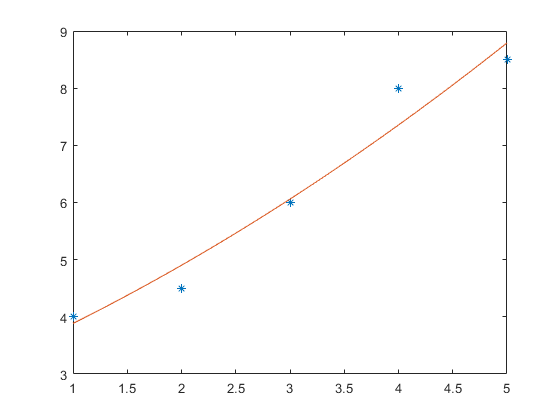

plot(x,y,'*')
hold on
plot(xx,yy)

disp(S)

$$0.06944\,x^{2}+0.8102\,x+3.005$$

delta = (y - least_squares(x,y,omega,varphi,x))

delta =     0.1157   -0.4028   -0.0602    0.6435   -0.2917


disp('均方误差')

均方误差


disp(sqrt(sum(delta.^2)))

    0.8237



disp('最大误差')

最大误差


disp(max(abs(delta)))

    0.6435

